# Convolutions

Here is the closing price of Bitcoin over the past month.

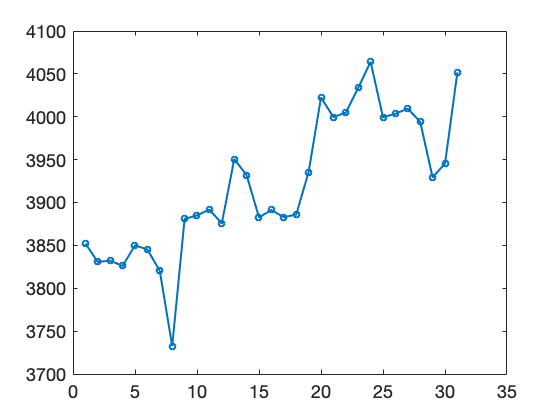

bc = webread('https://api.coindesk.com/v1/bpi/historical/close.json');
data = jsondecode(bc);
v = struct2cell(data.bpi);
v = cat(1,v{:});
plot(v,'-o')

## Moving average

We superimpose a sliding 4-day average of the values. It's a good deal smoother than the original. 

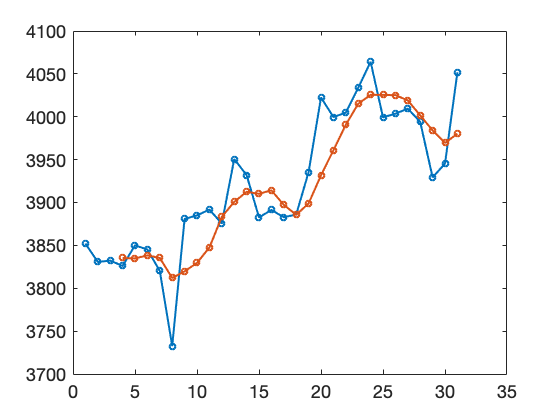

for i = 4:31
    z(i) = (v(i) + v(i-1) + v(i-2) + v(i-3)) / 4;
end
z(1:3) = NaN;  % not a number
hold on, plot(z,'-o')

## Weighted moving average

Here we modify the average to weight the most recent past more heavily in each case. 

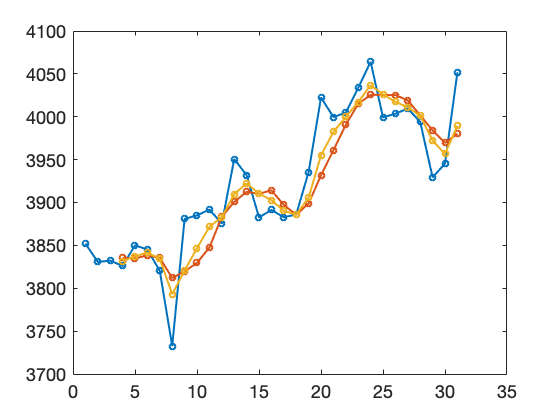

w = [4 3 2 1];
for i = 4:31
    z(i) = (w(1)*v(i) + w(2)*v(i-1) + w(3)*v(i-2) + w(4)*v(i-3)) / sum(w);
end
z(1:3) = NaN;  % not a number
hold on, plot(z,'-o')